ncfile = NetCDFFile('run10FinalLeticia.nc');

% initialize wvt from file
wvt = WVTransform.waveVortexTransformFromFile(ncfile.path, iTime=Inf);

The operation phase with variables {phase,} has been removed and the operation phase with variables {phase,} has been added.
The operation conjPhase with variables {conjPhase,} has been removed and the operation conjPhase with variables {conjPhase,} has been added.
The operation A0t with variables {A0t,} has been removed and the operation A0t with variables {A0t,} has been added.
The operation Apt with variables {Apt,} has been removed and the operation Apt with variables {Apt,} has been added.
The operation Amt with variables {Amt,} has been removed and the operation Amt with variables {Amt,} has been added.
The operation uvMax with variables {uvMax,} has been removed and the operation uvMax with variables {uvMax,} has been added.
The operation wMax with variables {wMax,} has been removed and the operation wMax with variables {wMax,} has been added.
The operation zeta_z with variables {zeta_z,} has been removed and the operation zeta_z with variables {zeta_z,} has been added.
The oper

t = ncfile.readVariables('t');

Only 14 vertical modes? 22 vertical grid points?

FMatrix=wvt.FMatrix;
GMatrix=wvt.GMatrix;

UAm=wvt.UAm;
UAp=wvt.UAp;
[AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);

UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );

u2 = zeros(14,44,22);

for jind = 1:wvt.Nj
    F2this = FMatrix(jind,:).^2;
    for Kind = 1:length(wvt.kRadial)
        u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
    end
end

UAm=wvt.UAm;
UAp=wvt.UAp;
[AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(UAm,UAp);

UA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

u2 = zeros(14,44,22);

for jind = 1:wvt.Nj
    F2this = FMatrix(jind,:).^2;
    for Kind = 1:length(wvt.kRadial)
        u2(jind,Kind,:)=UA2(jind,Kind)*F2this;
    end
end

VAm=wvt.VAm;
VAp=wvt.VAp;
[AmWavenumber,ApWavenumber] = wvt.transformToRadialWavenumber(VAm,VAp);

VA2= (AmWavenumber.*conj(AmWavenumber) + ApWavenumber.*conj(ApWavenumber));

v2 = zeros(14,44,22);

for jind = 1:wvt.Nj
    F2this = FMatrix(jind,:).^2;
    for Kind = 1:length(wvt.kRadial)
        v2(jind,Kind,:)=VA2(jind,Kind)*F2this;
    end
end

u2v2=u2+v2;
uvVariance=squeeze(sum(sum(u2v2)));

%uvVarianceInterp=
plot(flipup(uvVariance),wvt.z)

# From Spatial 

u2=(wvt.u).^2;
v2=(wvt.v).^2;

u2Mean=squeeze(mean(mean(u2,1),2));
v2Mean=squeeze(mean(mean(v2,1),2));

HVVariance =u2Mean + v2Mean;

plot(HVVariance,wvt.z);
Ekj = wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );

# From toolbox

%Stratification 1 - Exponential
% f0=2*7.2921e-5*sind(latitude);
latExp=33;
L_gm = 1300;
N0 = 3*2*pi/3600;
N2funcExp = @(z) N0*N0*exp(2*z/L_gm);
LzExp=4000;
tic
igw = InternalGravityWaveSpectrum(N2funcExp,LzExp,nModes=60,nK=64,latitude=latExp);
toc

Elapsed time is 88.287325 seconds.


params=[3,3/2,1];
energySpectrum = igw.gmSpectrumFunctionHandle(params);

params=[3,3/2,3.5]; %j_star,slope,GMAmplitude
E_model= wvt.transformToRadialWavenumber( wvt.Apm_TE_factor .* (abs(wvt.Ap).^2 + abs(wvt.Am).^2) );
E_model=E_model./(wvt.kRadial(2)-wvt.kRadial(1));
j=wvt.j;
kRadial=wvt.kRadial;

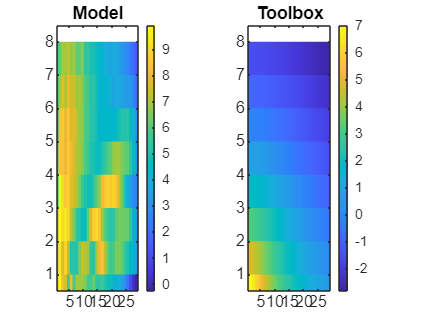

val = 1.2360e+07


val = igw.objectiveFunction(params,kRadial,j,E_model)

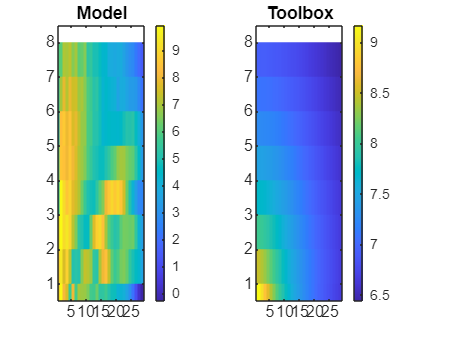

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 8706293.197197 



ans =   918.6726    0.5767  791.2083


fun= @(paramsGuess) igw.objectiveFunction(paramsGuess,kRadial,j,E_model);
tic
fminsearch(fun,params)

toc

Elapsed time is 149.748855 seconds.
